## Covariance Matrix Demonstration

Use a 16-element ULA with 10 GHz spacing.

fc = 10e9;
spacing = freq2wavelen(fc)/2;
elementgrid = [4 4];
nelements = prod(elementgrid);
ula = phased.ULA(NumElements=nelements,ElementSpacing=spacing);

Next create a receiver with 10 dB noise figure.

receiver = phased.Receiver(Gain=20,...
    NoiseMethod="Noise figure",NoiseFigure=10,ReferenceTemperature=300);

## Noise Only Covariance Matrix

First we investigate the covariance matrix when there is only noise present in the received signal.

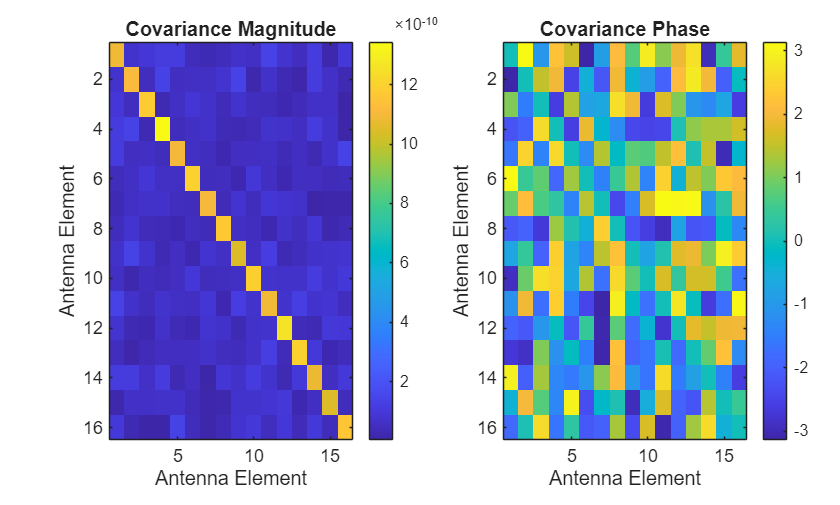

nSamples = 310;
sig = zeros(nSamples,nelements);
noiserx = receiver(sig);
helperPlotCovariance(noiserx);

## Single Signal Covariance Matrix

Next we investigate the covariance matrix when there is a signal arriving at some angle of arrival.

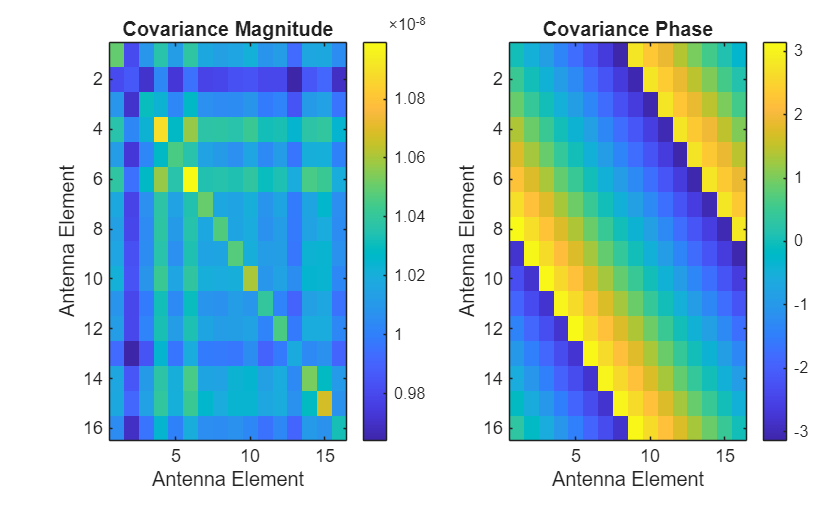

angOfArrival = -8;
signalMagnitude = 1e-6;
nSamples = 100;
sig = signalMagnitude*exp(1i*2*pi*rand(nSamples,1));
sigrx = collectPlaneWave(ula,sig,[angOfArrival;0],fc);
sigrx = receiver(sigrx);
helperPlotCovariance(sigrx)

## Free Space Loss

Free Space Path Loss is only valid in the far field. The following plot shows free space path loss as a function of distance for a signal at our wavelength.

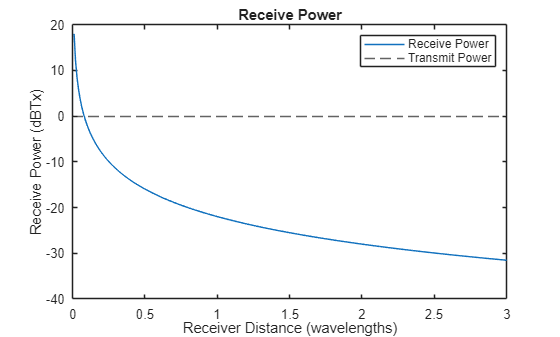

lambda = 1;
d = 0:lambda/100:lambda*3;
txpower = 1;
fspl = (4*pi*d/lambda).^2;
rxpower = (lambda./(4*pi*d)).^2*txpower;
ax = axes(figure);
plot(ax,d,pow2db(rxpower),DisplayName='Receive Power');
yline(ax,0,LineStyle='--',DisplayName='Transmit Power');
title(ax,'Receive Power');
ylabel(ax,'Receive Power (dBTx)');
xlabel(ax,'Receiver Distance (wavelengths)');
legend(ax);

## Helper Functions

function helperPlotCovariance(sig)
    samplecov = sig'*sig;
    tl = tiledlayout(figure,"horizontal");
    magax = nexttile(tl);
    phaseax = nexttile(tl);
    
    % Plot covariance magnitude
    imagesc(magax,abs(samplecov));
    colorbar(magax);
    title(magax,'Covariance Magnitude');
    ylabel(magax,'Antenna Element');
    xlabel(magax,'Antenna Element');

    % Plot covariance phase
    imagesc(phaseax,angle(samplecov));
    colorbar(phaseax);
    title(phaseax,'Covariance Phase');
    ylabel(phaseax,'Antenna Element');
    xlabel(phaseax,'Antenna Element');
    clim(phaseax,[-pi pi])
    
end